### **Communication Systems Laboratory**

**Lab 4: OFDM Transmission Using USRP**

**Students: **B11901006 臧逸新、B11901013 俞柏安、B11901101 謝函蓁

#### Wifi-Modulation Initialize

clc; clear; close all;
% Required Files:


%---------Re-generate signal option------%
% 0 for using stored signal 
% 1 for regenerating signal (using usrp)

%----------------------------------------%
global pilot_idx;
global data_idx;
global zero_idx;
global channel_est
global N_FFT;
global N_CP;
global fs;
global ts;
global fc;
%% Parameters
N_FFT = 64;  % FFT size
N_CP = 16;   % Cyclic prefix length
N_OFDM = N_FFT+N_CP; 
fs = 10e6;   % Sampling rate (Hz)
ts = 1/fs;   % Sampling time
fc = 915e6;  % Carrier frequency (Hz)


% Define subcarrier indices for 802.11a/g
pilot_idx = [12 26 40 54];   % Pilot subcarriers (1-based index)
data_idx = setdiff(1:N_FFT, [1:6, pilot_idx, N_FFT/2+1, 1:6, 60:64]); % Exclude DC, pilot, and unused guard bands
zero_idx = [1:6, N_FFT/2+1, 60:64];

% 5- OFDM symbols with STS, LTS;
% L_sig_5_head = 320;
% L_sig_5 =  L_sig_5_head + 5 * (N_OFDM);
% L_sig_100   = L_sig_5_head + 100 * (N_OFDM);
L_head = 320;
L_sig_100 = L_head + 100*N_OFDM;

% scaling of transmitted amplitude
send_amp = 0.1;

% color style
% '#003C76': Deep Blue
% '#939880': Tea Green
% '#875B75': Plum Purple
% '#DAC1AE': Skin Pink
% '#99755A': Brown
% '#393939': Black
save init.mat pilot_idx data_idx zero_idx ...
            channel_est N_FFT N_CP N_OFDM fs ts fc send_amp...
            L_sig_100 L_head

#### **Funcion Definition**

% initialize USRP receiver and transmitter
    
function radio_xx = USRP_init(rx_length, address, whichx)
    %TX_RX_INIT Summary of this function goes here
    %   Detailed explanation goes here
    platform = "N200/N210/USRP2";
    % address  = '192.168.10.2';
    USRPGain            = 5;  % Set USRP radio gain
    USRPCenterFrequency = 915*1e6;  % Set USRP radio center frequency
    
    if whichx == "tx"
        radio_xx = comm.SDRuTransmitter(...
                            'Platform',             platform, ...
                            'IPAddress',            address, ...
                            'CenterFrequency',      USRPCenterFrequency, ...
                            'Gain',                 USRPGain);
    elseif whichx == "rx"
        radio_xx = comm.SDRuReceiver(...
                        'Platform',             platform, ...
                        'IPAddress',            address, ...
                        'CenterFrequency',      USRPCenterFrequency, ...
                        'Gain',                 5, ...
                        'SamplesPerFrame',      rx_length, ...
                        'OutputDataType',       'double') ;
    end
                   
end

% generate single OFDM symbol
function ofdm_SYM = ofdm_generate(mod_size)
    %% Generate pilot tones (BPSK modulation)
    global pilot_idx;
    global data_idx;
    global N_FFT

    pilot_bits = [1, 1, 1, -1];
    X_pilot = pilot_bits + 0j; % Convert to complex symbols
    
    %% Generate data tones (16-QAM modulation)
    data_bits = randi([0 mod_size - 1], length(data_idx), 1); % Random 16-QAM symbols
    qam_mod = qammod(data_bits, mod_size, 'UnitAveragePower', true);

    %% Create OFDM symbol in frequency domain
    ofdm_SYM = zeros(N_FFT, 1);
    ofdm_SYM(data_idx) = qam_mod;  % Assign 4-QAM data
    ofdm_SYM(pilot_idx) = X_pilot; % Assign BPSK pilot tones
end

% add time-domain cyclic prefix for a single symbol
function sig_b = ofdm_addCP(sig_a)
    global N_FFT; global N_CP;
    sig_b = zeros(N_FFT + N_CP, 1);
    cyclic_prefix = sig_a(N_FFT-N_CP+1:end);
    sig_b(1:N_CP) = cyclic_prefix;
    sig_b(N_CP+1:end) = sig_a;
end

% remove time-domain cyclic prefix for a single symbol
function sig_c = ofdm_removeCP(sig_b)
    global N_CP;
    sig_c = sig_b(N_CP+1:end);
end

% generate a complete normalized STS 
function [STS, single_STS] = STS_generate()
    global N_FFT;
    STS_values = sqrt(13/6) * [0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, -1-1j, ...
                                0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, 0, 0, 0, 0, ...
                                -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, ...
                               0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0];
    
    single_STS = zeros(N_FFT, 1);
    single_STS(7:59) = STS_values;
    
    x_single_sts = ifft(ifftshift(single_STS));
    
    STS = zeros(length(x_single_sts)*2.5, 1);
    STS(1:N_FFT/2) = x_single_sts(N_FFT/2+1:end);
    for i = 0:1
        STS(i*length(x_single_sts)+ N_FFT/2+1 : (i+1)*length(x_single_sts)+ N_FFT/2) = x_single_sts;
    end
    single_STS = STS(1:16);
    STS = STS / mean(abs(STS));
end

% generate a complete normalized LTS
function [LTS, single_LTS] = LTS_generate()
    global N_FFT;
    LTS_values = [1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,0,1, ...
        -1, -1, 1, 1, -1, 1,-1, 1,-1,-1,-1,-1,-1, 1, 1,-1,-1, 1,-1,1,-1,1,1,1,1];
    
    single_LTS = zeros(N_FFT, 1);
    single_LTS(7:59) = LTS_values;
    
    x_single_lts = ifft(ifftshift(single_LTS)); % time domain
    
    LTS = zeros(length(x_single_lts)*2.5, 1);
    LTS(1:N_FFT/2) = x_single_lts(N_FFT/2+1:end);
    for i = 0:1
        LTS(i*length(x_single_lts)+ N_FFT/2 +1 : (i+1)*length(x_single_lts)+ N_FFT/2 ) = x_single_lts;
    end
    
    LTS = LTS / mean(abs(LTS));
end

% fast trim (may not be correct but faster)
function [sec_beg, sec_end] = fast_trim(buffer, plot_len, sec_blank)
    crt = 0.01;
    sec_beg = sec_blank;
    for ii = 1:length(buffer)
        if buffer(ii)>crt
            sec_beg = ii;
            break
        end
    end
    sec_beg = sec_beg - sec_blank + 1;
    sec_end = sec_beg + plot_len + 2*sec_blank;
end

% find starts
function [sts_start, lts_start, ofdm_start] = find_starts(buffer_trimmed,sec_beg, single_LTS)
    conv_sig_LTS = conv(buffer_trimmed, flipud(conj(single_LTS)), "valid"); % inden range should be adjusted

    crit_lts = max(abs(conv_sig_LTS))-0.3;
    lts_peaks = find(abs(conv_sig_LTS) >= crit_lts);
    lts_start = sec_beg + lts_peaks(1)-1;
    ofdm_start = lts_start + 2*64;
    sts_start = lts_start - 32 - 160;
end

**[Part 1] Cross-USRP Wi-Fi-Based OFDM transmission (60 points)**

**Network Configuration**

**(1) **Describe your network configuration that allows the computer to control two USRPs. More specifically, please describe the network configuration at your computer (IP & subnet mask) and the IP addresses you assign for the two USRPs.

**Ans:**

USRP 1:

IP address = 192.168.10.1

Subnet mask = 255.255.255.0

Default gateway = 192.168.10.2

USRP 2:

IP address = 192.168.20.1

Subnet mask = 255.255.255.0

Default gateway = 192.168.20.2

**(2)** Explain how the above network configuration allows you to control two USRPs from your computer.

**Ans:**

Default gateway is set to the USRP's IP setup.

For each USRP, since subnet mask is set to 24 bits, the host ID (the first 24 bits, i.e. the first three sections) of the NIC's IP address are set to the same as the default gateway so that they are in the same subnet. The network ID (the last 8 bits, i.e. the last section) is set differently so that they are separate identities within their subnet.

The two USRP's NIC's IP address are set differently so that the computer can identify them.

When we execute "findsdru()", matlab scan through all NIC on the computer and successfully communicate with the USRPs through those NICs.

**Resolve Cross-Device Synchronization Issues**

Transmit a frame with 100 OFDM data symbols with 4-QAM modulation using USRP 1. Receive the frame with USRP 2. Develop a strategy that allows complete capture of a whole frame at USRP 2.

For example, you can try:

`•` Append/prepend zeros to the transmit frame to make the beginning and the end of the frame visually apparent.

`•` Capture a longer range in the time domain than the transmitted frame.

`•` Retransmission scheme with ACK/NAK from USRP 2.

`•` ...

**(3) **Explain the strategy you employ to ensure complete capture of a whole frame at USRP 2.

**(4) **Using the above proposed strategy, plot the received signal in the time domain at USRP 2. Mark the beginning and the end of the frame to show a successful capture of a whole frame.

**Generate a 100-symbol frame**

clc; clear; close all;
load("init.mat")

L_head = 320;
L_sig_100 = L_head + 100*N_OFDM;

sig_100 = zeros(L_sig_100, 1);
data_tx = zeros(5*48, 1);

% generate frame head
[STS, single_STS] = STS_generate();
[LTS, single_LTS] = LTS_generate();
sig_100(1:length(STS)) = STS;
sig_100(length(STS)+1:length(STS)+length(LTS))= LTS;

% generate 100 OFDM Symbols
for i = 0:(100-1)
    x_fft = ofdm_generate(4); % one OFDM symbol, 4-qam
    x = ifft(ifftshift(x_fft));
    x_cp = ofdm_addCP(x);
    sig_100(L_head + i*(N_OFDM)+1 : L_head+(i+1)*(N_OFDM)) = x_cp;
    
    data_tx(48*i+1 : 48*(i+1)) = x(data_idx);
end
sig_100(L_head+1:end) = sig_100(L_head+1:end)/mean(abs(sig_100(L_head+1:end)));

bits_tx = qamdemod(data_tx, 4, 'gray', OutputType='bit', UnitAveragePower=true);
padded_sig_100 = send_amp*[zeros(100, 1); sig_100; zeros(100, 1)];

REGEN_SIG_FLAG_100 = 1

save sig_100_send.mat sig_100 STS LTS

**Send the frame**

l = length(padded_sig_100);
radio_Tx = USRP_init(l, '192.168.10.2', "tx");
radio_Rx = USRP_init(l, '192.168.20.2', "rx");
buffer = zeros(5*l, 1);

% Transmit the frame we generate

for ii = 1:3
    if ii == 2
        tunderrun = radio_Tx(padded_sig_100);
    else
        tunderrun = radio_Tx(complex(zeros(l, 1)));
    end
    [rcvdSignal, ~, toverflow] = step(radio_Rx);
    buffer((1+(ii-1)*l):(ii*l)) = rcvdSignal;
end
% Keep reception for 2 frames
for ii = 4:5
    [rcvdSignal, ~, toverflow] = step(radio_Rx);
    buffer((1+(ii-1)*l):(ii*l)) = rcvdSignal;
end 

release(radio_Tx)
release(radio_Rx)

buffer =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


**Trim and plot**

[sec_beg, sec_end] = fast_trim(buffer, 8500, 100);

single_LTS = LTS(end-64+1:end);
[sts_start, lts_start, ofdm_start] = find_starts(buffer(sec_beg:sec_end), sec_beg, single_LTS)

sts_start = 11407

lts_start = 11599

ofdm_start = 11727

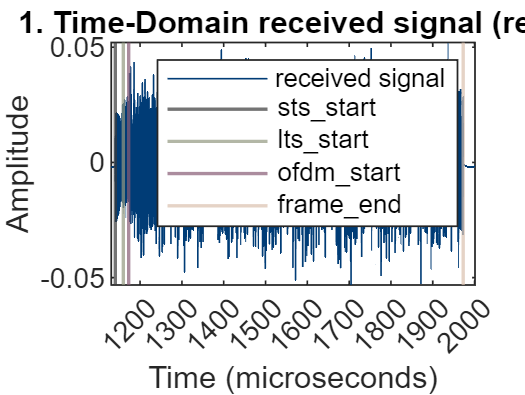


% plot the location of estimated starts
figure;
time_vector = (sec_beg:sec_end);
plot(time_vector, real(buffer(sec_beg:sec_end)), 'Color', '#003C76');
hold on
xline(sts_start, 'Color', '#393939','LineWidth', 1);
xline(lts_start, 'Color', '#939880','LineWidth', 1);
xline(ofdm_start, 'Color', '#875B75','LineWidth', 1);
xline(sts_start + L_sig_100, 'Color', '#DAC1AE','LineWidth', 1);
hold off
xlim([sec_beg sec_end])
xt = xticks;
xticklabels(xt * ts*1e6);
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('4. Time-Domain received signal (real)');
legend('received signal','sts\_start', 'lts\_start', 'ofdm\_start', 'frame\_end')


save sig_100_recv.mat buffer sts_start lts_start ofdm_start

**(5) **Without CFO correction, plot the received constellation (only the data tones). Do you observe the constellation rotating?

clc; clear;
load("init.mat")
load("sig_100_recv.mat")



**(6)** Estimate the CFO of the received frame. What is the estimated CFO? Also, please explain your CFO estimation process. For instance, whether the CFO is estimated from STS, LTS, or both.

**(7)** Apply CFO correction to the received frame and then estimate the channel. Plot (i) the magnitude and (ii) the phase of the estimated channel vs subcarrier, with zero subcarrier in the middle. Describe and discuss the figure.

**(8) **Perform equalization on the received frame. Plot the CFO-corrected and equalized received constellation (only the data tones). Do you still observe the constellation rotating?

**(9)** Use the four pilot tones to track the residual CFO and further correct the data tones accordingly. With the assistance of the pilot tones, plot the received constellation (only the data tones). What do you observe?

**(10)** Demodulate the received signal at USRP 2 and calculate the bit error rate for this single frame. What is the BER? The goal is to obtain no (or very few) bit errors.

**(11)** Change the modulation to 16-QAM and repeat the experiment. Plot the CFO corrected, equalized, and pilot-assisted constellations as in (9).

**(12)** Following (11), what is the BER using 16-QAM modulation? How does it compare to the BER using 4-QAM in (10)?

**Establish a Framework to Transmit Multiple Frames**

Expanding your framework to transmit multiple frames, each with different random bits.

**(13) **Transmit and receive 20 frames, each with 100 OFDM symbols using 16-QAM modulation. Calculate the BER for each of the 20 frames. Plot BER per frame vs frame number, and provide the total BER for the 20 frames. The goal is to show that your transmission framework is robust enough that you can consistently collect usable experimental data. Thus, the BER should be rather consistent across different frames.

**Send and receive 20 frames**

buffer =   -0.0000 + 0.0000i
  -0.0000 + 0.0001i
   0.0000 + 0.0000i
   0.0001 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


sts_start = 11640

lts_start = 11832

ofdm_start = 11960

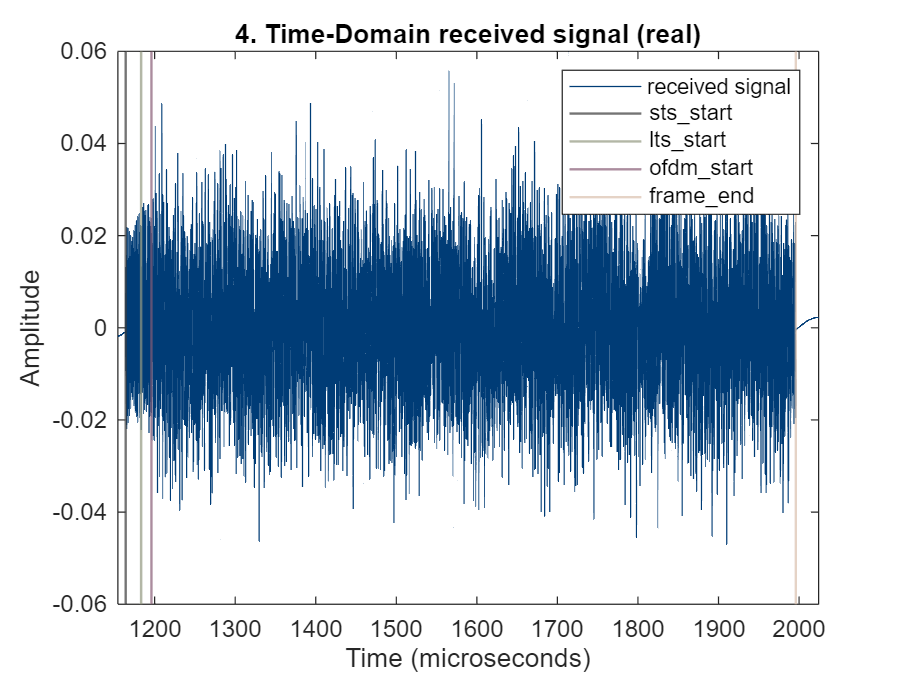

clc; clear;
load("init.mat")
load("sig_100_send.mat")

padded_sig_100 = send_amp*[zeros(100, 1); sig_100; zeros(100, 1)];
l = length(padded_sig_100);
radio_Tx = USRP_init(l, '192.168.10.2', "tx");
radio_Rx = USRP_init(l, '192.168.20.2', "rx");
buffer_20 = zeros(5*l, 20);

for jj = 1:20
    for ii = 1:3
        if ii == 2
            tunderrun = radio_Tx(padded_sig_100);
        else
            tunderrun = radio_Tx(complex(zeros(l, 1)));
        end
        [rcvdSignal, ~, toverflow] = step(radio_Rx);
        buffer_20((1+(ii-1)*l):(ii*l), jj) = rcvdSignal;
    end
    % Keep reception for 2 frames
    for ii = 4:5
        [rcvdSignal, ~, toverflow] = step(radio_Rx);
        buffer_20((1+(ii-1)*l):(ii*l), jj) = rcvdSignal;
    end 
end
release(radio_Tx)
release(radio_Rx)
save sig_100_recv_20.mat buffer_20

**(14)** Calculate the BER per subcarrier based on the received 20 frames. Plot BER vs subcarrier. Describe and analyze the BER figure you obtain. Is there frequency-dependent BER behavior? If some subcarriers experience higher bit errors, what do you think is the reason?

**(15)** Please select three (or more) transmission distances (please measure the distance). At each distance, transmit and receive 20 frames, each with 100 OFDM symbols using 16-QAM modulation as in (13). Plot the total BER vs transmission distance, showing that the BER increases with distance.

**[Part 2] Demo (40 points, no report needed)**